# Ejemplo 1

En este ejemplo se podrá observar el proceso de muestreo (discretización) de una señal de timpo continuo.

Inicialmente se genera la función de tiempo continuo. Observe que se trata de la combinación de dos armónicos.

t=0:0.001:1; %segundos
f1= 4; %Hz
f2= 6; %Hz
xt=2*cos(2*pi*f1*t)+3*sin(2*pi*f2*t);

Gráficando de la señal de tiempo continuo, para las señales de tiempo continuo se utiliza la función plot para visualizar un trazo continuo.

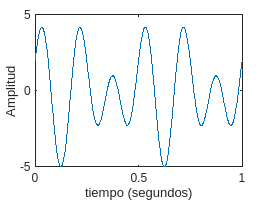

figure
plot(t,xt)
xlabel('tiempo (segundos)')
ylabel('Amplitud')

## Discretización de la señal análoga

Para este ejemplo se considera un periodo de muestreo de 1/24 de segundo que se utilizará para discretizar la señal continua. La variable nT representa los instantes en los que se captura un valor de la señal análoga

Ts=1/24; % Periodo de muestreo
nT=0:Ts:1;
xnT=2*cos(2*pi*f1*nT)+3*sin(2*pi*f2*nT);

Observe que la unidad de tiempo aun no ha cambiado, siguen siendo segundos. Cada muestra está ubicada en el instante de tiempo donde se captura el valor de la señal análoga.

Para graficar las señales de tiempo discreto se usa la función stem que dibuja una linea vertical en cada punto, observe que no hay trazo continuo entre muestras.

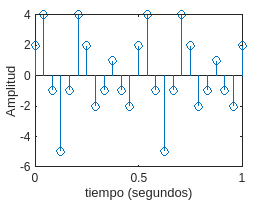

figure
stem(nT,xnT)
xlabel('tiempo (segundos)')
ylabel('Amplitud')

En la siguiente gafica se observa la superposición de las muestras capturadas con la señal análoga

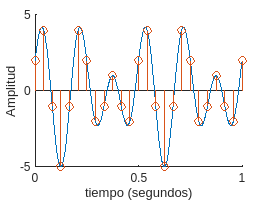

figure
hold on
plot(t,xt)
stem(nT,xnT)
xlabel('tiempo (segundos)')
ylabel('Amplitud')
hold off

A continuación se obtendrá la señal de tiempo discreto (digital). La frecuencia de muestreo (Fs) es el inverso multiplicativo del periodo de muestreo. Se consideran 24 muestras para representar la señal

Fs=1/Ts;
N=Fs;
n=0:N-1;
xn=2*cos(2*pi*(f1/Fs)*n)+3*sin(2*pi*(f2/Fs)*n);

Observe que para este último caso se realiza la división de la frecuancia del armónico entre la frecuencia de muestreo ¿Qué explicación tiene este procedimiento?

Gráfica de la señal de tiempo discreto (digital). Se observa que la unidad en el eje orizontal es diferente, ahora son muestras y corresponden a valores enteros.

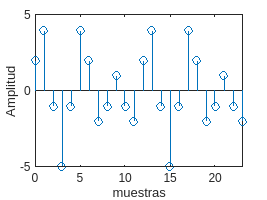

figure,
stem(n,xn)
xlabel('muestras')
ylabel('Amplitud')